**Question 1**

clf

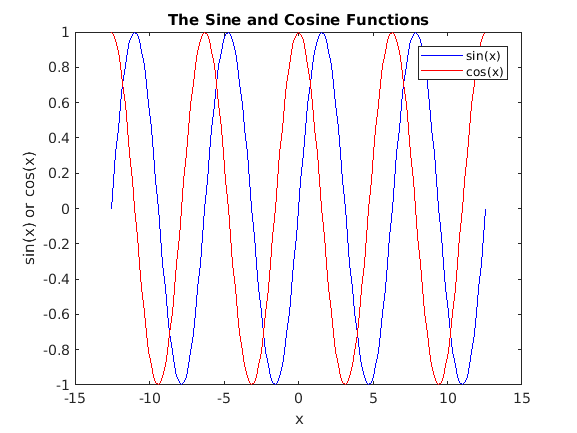


% Plotting sin(x), cos(x)
x = -4*pi : pi/20 : 4*pi;

figure(1)
plot(x, sin(x), 'b-', x, cos(x), 'r-')
xlabel('x')
ylabel('sin(x) or cos(x)')
title('The Sine and Cosine Functions')
legend('sin(x)', 'cos(x)')


%hold on
%plot([-5 -5], [-1 1])

**Question 2**

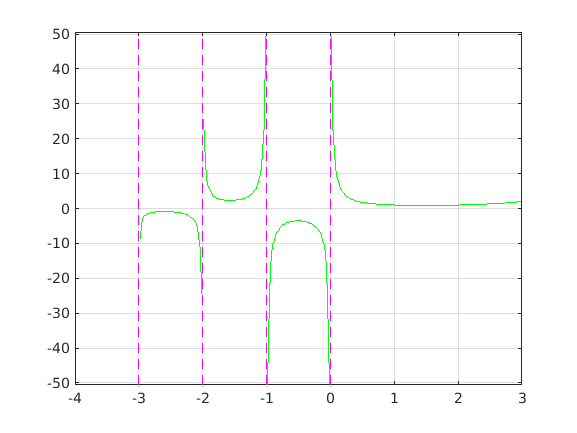

% evaluating gamma, but avoiding the asymptotes
% that are at x = -3, -2, -1, 0
% plot magenta dashed lines at asymptotes

xs = -3: 0.02 :3;
ys = gamma(xs);

plotGammaWithAsymptotes(xs, ys)

**Question 3**

Plotting y = 2x^2 + 8x-1 on [-5,5] and draw y = 0, x = 0 and plot the intercepts of the graph along with the vertex as circles. Then label the x and y axes and place a legend on the graph. 

xs = -5 : 0.01 : 5; 
y = @(x) 2*x .^ 2 + 8*x - 1;
%ys = y(xs);

getIntercepts(xs, y)

Subscript indices must either be real positive integers or logicals.

Error in getIntercepts (line 18)
            roots(counter) = xs(i+1);

%xMin = min(xs); xMax = max(xs); 
%yMin = min(ys); yMax = max(ys);

% Get the yvalues using the original function: 
ys = y(xs);
% Get indices in ys where y changes sign (indices of x roots)
indexChangeList = int32(find(diff(sign(ys)))); %changing to ints otherwise are doubles!
indexChangeList

indexChangeList = 1×2 int32 row vector
    88   513



%Getting the x-roots
roots = int32(zeros(1, length(indexChangeList)))

roots = 1×2 int32 row vector
   0   0



counter = 0;
for i = indexChangeList
    if abs(y(xs(i))) < abs(y(xs(i+1)))
        roots(counter) = xs(i);
    else
        roots(counter) = xs(i+1);
    end
    counter = counter + 1; 
end

Subscript indices must either be real positive integers or logicals.


yIntercept = y(0); % is the y-value where x = 0

%{
clf
% Plotting main graph
plot(x, y, 'b-')
axis([xMin-2, xMax+2, yMin, yMax])
grid on
hold on 

% Plotting the vertex
a = 2; b = 8; c = -1;
[vx, vy] = [-b/(2*a), c - b^2/(4*a)];
plot(vx, vy, 'ko')

% And plotting x,y intercepts
xIntercept = 

% Plotting the x and y-axes
plot([0 0], [yMin yMax], 'k-') % y-axis
plot([xMin xMax], [0 0]) % x-axis
%}